#                                     EJERCICIO DE AUDIO

Diseñe una aplicacion que permita realizar efectos audio por medio de operaciones, los efectos realizados son eco, reverberacion, flanging, pannin, tremolo, la potencia de estos efectos debe ser dinamica, el programa debe grabar la voz y poder pausar, parar y reanudar la grabacion en cualquier momento 

#### Solucion 

Herramientas utilizadas:

- App designer

- Matlab puro

- Audio system toolbox

**NOTA: **el codigo de la aplicacion esta embebido dentro de los callbacks correspondientes a los componentes GUI de app designer, no se utilizaron diagramas de bloque ni simulink solamente algoritmos matematicos en codigo matlab.

#### Interfaz de la aplicacion 

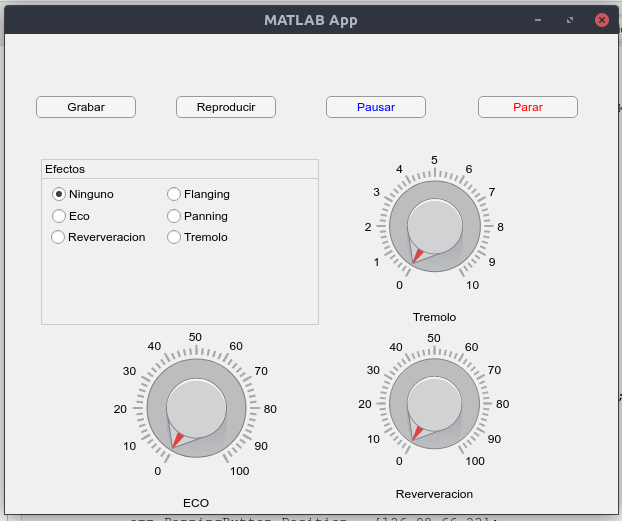

#### Codigo de la aplicacion 

%classdef ejercicio < matlab.apps.AppBase

    % Properties that correspond to app components
    properties (Access = public)
        UIFigure                matlab.ui.Figure
        GrabarButton_2          matlab.ui.control.Button
        PararButton             matlab.ui.control.Button
        ReproducirButton        matlab.ui.control.Button
        PausarButton            matlab.ui.control.Button
        EfectosButtonGroup      matlab.ui.container.ButtonGroup
        NingunoButton           matlab.ui.control.RadioButton
        EcoButton               matlab.ui.control.RadioButton
        FlangingButton          matlab.ui.control.RadioButton
        PanningButton           matlab.ui.control.RadioButton
        ReververacionButton     matlab.ui.control.RadioButton
        TremoloButton           matlab.ui.control.RadioButton
        ECOKnobLabel            matlab.ui.control.Label
        ECOKnob                 matlab.ui.control.Knob
        ReververacionKnobLabel  matlab.ui.control.Label
        ReververacionKnob       matlab.ui.control.Knob
        TremoloKnobLabel        matlab.ui.control.Label
        TremoloKnob             matlab.ui.control.Knob
    end

    % Callbacks that handle component events
    methods (Access = private)

        % Button pushed function: GrabarButton_2
        function GrabarButton_2Pushed(app, event)
            global audioObject
            global ms
            audioObject = audiorecorder;
            %duration = str2double(app.DuracionTextArea.Value{1});
            ms = msgbox('Grabando...');
            record(audioObject);
            %recordblocking(audioObject, duration);
            %delete(ms);
            
            assignin('base','audioObject', audioObject);
            %msgbox('Grabado exitosamente!');
        end

        % Button pushed function: ReproducirButton
        function ReproducirButtonPushed(app, event)
            global audioObject;
            global disparador;
            disp(disparador)
            audioObject = evalin('base','audioObject')
            y = getaudiodata(audioObject);
            Fs = audioObject.SampleRate;                            
           switch disparador
                case 'Eco'
                    multiplicador = app.ECOKnob.Value/100;
                    format bank;
                    %disp(multiplicador)
                    delay = multiplicador; % o.5 segundos de retraso maximo un segundo 
                    alpha = 0.65; % fuerza del eco                 
                    D = round(delay*Fs);
                    x = zeros(size(y));
                    x(1:D) = y(1:D);
                    disp (D)
                    for i=D+1:length(y)
                        x(i) = y(i) + alpha*y(i-D);
                    end
                    sound(x, Fs);
                    play(audioObject);    %disp(selectedButton);
                    
                case 'Reververacion'
                    %disp(selectedButton);
                    multiplicador = app.ReververacionKnob.Value/100;
                    format bank;
                    disp(multiplicador)                    
                    delay1 = round(Fs*0.008); % FIR Delay
                    delay2 = round(Fs*0.025); % IIR Delay
                    coef = multiplicador; % IIR Decay rate
                    yy = filter([1 zeros(1,delay1) coef],[1 zeros(1,delay2) -coef],y);                 
                    sound(yy, Fs);
                    play(audioObject);
                case 'Flanging'
                    lfo_freq = 1/3; % LFO Freq (Hz)
                    lfo_amp = 0.004; % LFO Amp (sec)
                    lfo = 2+sawtooth(2*pi*lfo_freq*(1:length(y))/Fs,0.5); % Generate triangle wave
                    index = round((1:length(y))-Fs*lfo_amp*lfo);
                    index(index<1) = 1;
                    index(index>length(y)) = length(y);
                    x=y; 
                    for j=1:length(y);
                        x(j) = x(j)+y(index(j));
                    end
                    sound(x, Fs);
                    play(audioObject);
                case 'Panning'
                    %disp(selectedButton);
                    initial_angle = -40; %in degrees
                    final_angle = 40; %in degrees
                    segments = 32;
                    angle_increment = (initial_angle - final_angle)/segments * pi / 180;
                    lenseg = floor(length(y)/segments) - 1;
                    pointer = 1;
                    angle = initial_angle * pi / 180; %in radians
                    x=[[];[]];
                    for i=1:segments
                    A =[cos(angle), sin(angle); -sin(angle), cos(angle)];
                    stereox = [y(pointer:pointer+lenseg)' ; y(pointer:pointer+lenseg)'];
                    x = [x, A * stereox];
                    angle = angle + angle_increment; pointer = pointer + lenseg;
                    end;                    
                    sound(x', Fs);
                    play(audioObject);
                case 'Tremolo'                 
                    multiplicador = app.TremoloKnob.Value;                    
                    index = 1:length(y);
                    Fc = multiplicador;
                    alpha = 0.5;                    
                    trem=(1+ alpha*sin(2*pi*index*(Fc/Fs))');
                    x = trem.*y;
                    sound(x, Fs);
                    play(audioObject);
                case 'Ninguno'
                    %disp(selectedButton);
                    sound(y, Fs);
                    play(audioObject);
                otherwise
                    disp('no ha seleccionado nada!');
                    play(audioObject);
            end
            
            
            
        end

        % Selection changed function: EfectosButtonGroup
        function EfectosButtonGroupSelectionChanged(app, event)
            selectedButton = app.EfectosButtonGroup.SelectedObject.Text;
            global disparador;
            switch selectedButton
                case 'Eco'
                    %disp(selectedButton);
                    disparador = selectedButton;
                case 'Reververacion'
                    %disp(selectedButton);
                    disparador = selectedButton;
                case 'Flanging'
                    %disp(selectedButton);
                    disparador = selectedButton;
                case 'Panning'
                    %disp(selectedButton);
                    disparador = selectedButton;
                case 'Tremolo'    
                    %disp(selectedButton);
                    disparador = selectedButton;
                case 'Ninguno'
                    %disp(selectedButton);
                    disparador = selectedButton;
                otherwise
                    %disp('no ha seleccionado nada!');
                    disparador = "nada ";
            end
            
        end

        % Button pushed function: PararButton
        function PararButtonPushed(app, event)
            global audioObject;
            global ms 
            delete(ms);
            msgbox('Grabado exitosamente!');
            stop(audioObject);
        end

        % Callback function
        function DuracionTextAreaValueChanged(app, event)
            global value;
            value = app.DuracionTextArea.Value;
            
        end

        % Button pushed function: PausarButton
        function PausarButtonPushed(app, event)
            global audioObject;
            if(isrecording(audioObject))
                pause(audioObject);
            else
                resume(audioObject); 
            end
            
            
        end
    end

    % Component initialization
    methods (Access = private)

        % Create UIFigure and components
        function createComponents(app)

            % Create UIFigure and hide until all components are created
            app.UIFigure = uifigure('Visible', 'off');
            app.UIFigure.Position = [100 100 613 480];
            app.UIFigure.Name = 'MATLAB App';

            % Create GrabarButton_2
            app.GrabarButton_2 = uibutton(app.UIFigure, 'push');
            app.GrabarButton_2.ButtonPushedFcn = createCallbackFcn(app, @GrabarButton_2Pushed, true);
            app.GrabarButton_2.Position = [32 397 100 22];
            app.GrabarButton_2.Text = 'Grabar';

            % Create PararButton
            app.PararButton = uibutton(app.UIFigure, 'push');
            app.PararButton.ButtonPushedFcn = createCallbackFcn(app, @PararButtonPushed, true);
            app.PararButton.FontColor = [1 0 0];
            app.PararButton.Position = [474 397 100 22];
            app.PararButton.Text = 'Parar';

            % Create ReproducirButton
            app.ReproducirButton = uibutton(app.UIFigure, 'push');
            app.ReproducirButton.ButtonPushedFcn = createCallbackFcn(app, @ReproducirButtonPushed, true);
            app.ReproducirButton.Position = [172 397 100 22];
            app.ReproducirButton.Text = 'Reproducir';

            % Create PausarButton
            app.PausarButton = uibutton(app.UIFigure, 'push');
            app.PausarButton.ButtonPushedFcn = createCallbackFcn(app, @PausarButtonPushed, true);
            app.PausarButton.FontColor = [0 0 1];
            app.PausarButton.Position = [322 397 100 22];
            app.PausarButton.Text = 'Pausar';

            % Create EfectosButtonGroup
            app.EfectosButtonGroup = uibuttongroup(app.UIFigure);
            app.EfectosButtonGroup.SelectionChangedFcn = createCallbackFcn(app, @EfectosButtonGroupSelectionChanged, true);
            app.EfectosButtonGroup.Title = 'Efectos';
            app.EfectosButtonGroup.Position = [37 190 278 166];

            % Create NingunoButton
            app.NingunoButton = uiradiobutton(app.EfectosButtonGroup);
            app.NingunoButton.Text = 'Ninguno';
            app.NingunoButton.Position = [11 120 67 22];
            app.NingunoButton.Value = true;

            % Create EcoButton
            app.EcoButton = uiradiobutton(app.EfectosButtonGroup);
            app.EcoButton.Text = 'Eco';
            app.EcoButton.Position = [11 98 65 22];

            % Create FlangingButton
            app.FlangingButton = uiradiobutton(app.EfectosButtonGroup);
            app.FlangingButton.Text = 'Flanging';
            app.FlangingButton.Position = [126 120 68 22];

            % Create PanningButton
            app.PanningButton = uiradiobutton(app.EfectosButtonGroup);
            app.PanningButton.Text = 'Panning';
            app.PanningButton.Position = [126 98 66 22];

            % Create ReververacionButton
            app.ReververacionButton = uiradiobutton(app.EfectosButtonGroup);
            app.ReververacionButton.Text = 'Reververacion';
            app.ReververacionButton.Position = [10 77 99 22];

            % Create TremoloButton
            app.TremoloButton = uiradiobutton(app.EfectosButtonGroup);
            app.TremoloButton.Text = 'Tremolo';
            app.TremoloButton.Position = [126 77 66 22];

            % Create ECOKnobLabel
            app.ECOKnobLabel = uilabel(app.UIFigure);
            app.ECOKnobLabel.HorizontalAlignment = 'center';
            app.ECOKnobLabel.Position = [176 1 32 22];
            app.ECOKnobLabel.Text = 'ECO';

            % Create ECOKnob
            app.ECOKnob = uiknob(app.UIFigure, 'continuous');
            app.ECOKnob.Position = [142 57 100 100];

            % Create ReververacionKnobLabel
            app.ReververacionKnobLabel = uilabel(app.UIFigure);
            app.ReververacionKnobLabel.HorizontalAlignment = 'center';
            app.ReververacionKnobLabel.Position = [389 10 83 22];
            app.ReververacionKnobLabel.Text = 'Reververacion';

            % Create ReververacionKnob
            app.ReververacionKnob = uiknob(app.UIFigure, 'continuous');
            app.ReververacionKnob.Position = [385 66 91 91];

            % Create TremoloKnobLabel
            app.TremoloKnobLabel = uilabel(app.UIFigure);
            app.TremoloKnobLabel.HorizontalAlignment = 'center';
            app.TremoloKnobLabel.Position = [406 187 49 22];
            app.TremoloKnobLabel.Text = 'Tremolo';

            % Create TremoloKnob
            app.TremoloKnob = uiknob(app.UIFigure, 'continuous');
            app.TremoloKnob.Limits = [0 10];
            app.TremoloKnob.Position = [385 243 92 92];

            % Show the figure after all components are created
            app.UIFigure.Visible = 'on';
        end
    end

    % App creation and deletion
    methods (Access = public)

        % Construct app
        function app = ejercicio

            % Create UIFigure and components
            createComponents(app)

            % Register the app with App Designer
            registerApp(app, app.UIFigure)

            if nargout == 0
                clear app
            end
        end

        % Code that executes before app deletion
        function delete(app)

            % Delete UIFigure when app is deleted
            delete(app.UIFigure)
        end
    end
end

#### Realizado por:

            CRISTIAN LEONARDO ALAPE AVILA - 20172578091

            Inteligencia artificial 2020-3